% 1. Load the audio file
filePath = 'D:\pycharm\Senior_Project\code\wasapi_output.wav';
[audioData, fs] = audioread(filePath);

% 2. Separate the channels
mic1 = audioData(:, 1);
mic2 = audioData(:, 2);

% 3. Perform Cross-Correlation
[corr, lags] = xcorr(mic1, mic2);

% 4. Find the index of the maximum correlation
[~, maxIdx] = max(abs(corr));
delayInSamples = lags(maxIdx);

% 5. Convert samples to time (seconds)
delayInSeconds = delayInSamples / fs;

% 6. Display results
fprintf('Delay in samples: %d\n', delayInSamples);

Delay in samples: -162733


fprintf('Delay in seconds: %.6f\n', delayInSeconds);

Delay in seconds: -3.390271



% Optional: Calculate distance (speed of sound ~343 m/s)
distance = delayInSeconds * 343;
fprintf('Estimated distance difference: %.4f meters\n', distance);

Estimated distance difference: -1162.8629 meters


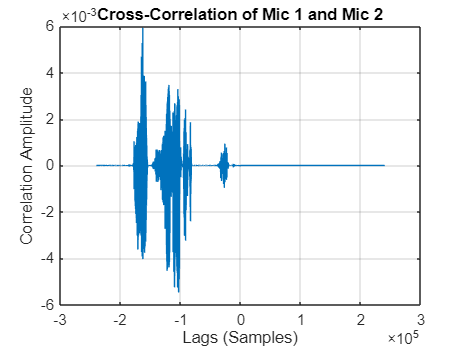


% 7. Plotting for verification
figure;
plot(lags, corr);
title('Cross-Correlation of Mic 1 and Mic 2');
xlabel('Lags (Samples)');
ylabel('Correlation Amplitude');
grid on;